im_eel = load_fish_image('fish-annotations\eel\anguilliform-anguilla-anguilla-annotated.png');
im_trout = load_fish_image('fish-annotations\trout\subcarangiform-oncorhynchus-mykiss-annotated.png');
im_mackerel = load_fish_image('fish-annotations\mackerel\carangiform-scomber-scombrus-annotated.png');
im_tuna = load_fish_image('fish-annotations\tuna\thunniform-thunnus-thynnus-annotated.png');
im_boxfish = load_fish_image('fish-annotations\boxfish\ostraciiform-ostracion-cubicum-annotated.png');

im_SL_eel = im_eel(:,1:round(0.984*size(im_eel,2)));
im_SL_trout = load_fish_image('fish-annotations\trout\subcarangiform-oncorhynchus-mykiss-annotated-SL.png');
im_SL_mackerel = load_fish_image('fish-annotations\mackerel\carangiform-scomber-scombrus-annotated-SL.png');
im_SL_tuna = load_fish_image('fish-annotations\tuna\thunniform-thunnus-thynnus-annotated-SL.png');
im_SL_boxfish = load_fish_image('fish-annotations\boxfish\ostraciiform-ostracion-cubicum-annotated-SL.png');

SLs = [size(im_SL_eel,2) size(im_SL_trout,2) size(im_SL_mackerel,2) size(im_SL_tuna,2) size(im_SL_boxfish,2)];
SL_max = max(SLs)

SL_max = 525

SL_min = min(SLs)

SL_min = 420

scales = SL_min./SLs

scales =     0.8571    0.8000    0.8284    1.0000    0.9032



im_eel = imresize(im_eel,scales(1),'nearest');
im_trout = imresize(im_trout,scales(2),'nearest');
im_mackerel = imresize(im_mackerel,scales(3),'nearest');
im_tuna = imresize(im_tuna,scales(4),'nearest');
im_boxfish = imresize(im_boxfish,scales(5),'nearest');

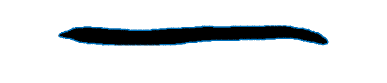

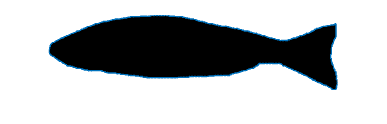

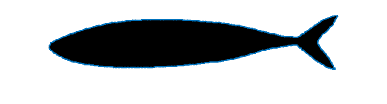

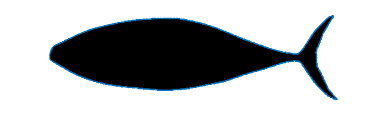

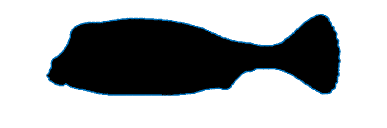

masks = {im_eel, im_trout, im_mackerel, im_tuna, im_boxfish};
boundaries = cell(length(masks),1);

for i=1:length(masks)
    boundaries{i} = get_boundary(masks{i});
    figure;
    imshow(masks{i})
    hold on
    adjust = size(masks{i},1); 
    XY = align_symmetrically(boundaries{i});
    plot(XY(:,1)+1,XY(:,2) +adjust/2 + 0.5,'LineWidth',1.5)
    hold off
end

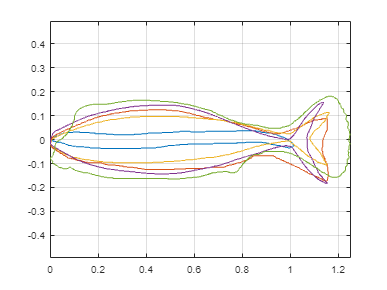

boundaries_norm = cell(length(masks),1);

figure;
hold on
for i=1:length(masks)
    boundaries_norm{i} = boundaries{i}/SL_min;
    XY = boundaries_norm{i};
    xmin = min(XY(:,1));
    ymin = min(XY(find(XY(:,1) <= 1),2));
    ymax = max(XY(find(XY(:,1) <= 1),2));
    yrange = ymax - ymin;
    XY = [XY(:,1)-xmin, (XY(:,2)-ymin-yrange/2)*-1];
    boundaries_norm{i} = XY;
    plot(XY(:,1),XY(:,2))
end
grid on
box on
axis equal
hold off

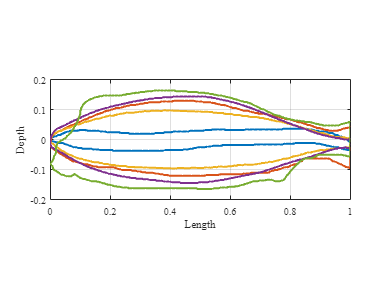

boundaries_body = cell(length(masks),1);
test = cell(length(masks),1);

figure;
hold on
for i=1:length(masks)
    fine_adjust = 0;
    XY = boundaries_norm{i};
    XY = XY(find(XY(:,1) <= 1),:);
    test{i} = XY;

    idx = find(XY == 1);
    XY1 = [XY(1:idx(1),1) XY(1:idx(1),2)];
    XY2 = [XY(idx(2):end,1) XY(idx(2):end,2)];

    XY1 = resampleNPoints(XY1,256);
    XY2 = resampleNPoints(XY2,256);
    XY1(end,1) = 1;
    XY = [XY1; XY2];
    XY(end+1,:) = XY(1,:);

    XY = align_symmetrically(XY);

    if i == 2
        fine_adjust = 0.005;
    end

    if i == 3
        XY = rotateBoundary(XY,-2,[0,0]);
        fine_adjust = 0.015;
    end

    XY(:,2) = XY(:,2) + fine_adjust;

    boundaries_body{i} = XY;

    plot(XY(:,1),XY(:,2), 'LineWidth',2)
end
grid on
box on
axis equal
ylim([-0.2 0.2])
xlim([0 1])
yticks(-0.2:0.1:0.2)
fontsize(10,'points')
fontname("Times New Roman")
ylabel("Depth","Interpreter","tex")
xlabel('Length','interpreter','tex')
set(gca,'TickLabelInterpreter','tex')
hold off

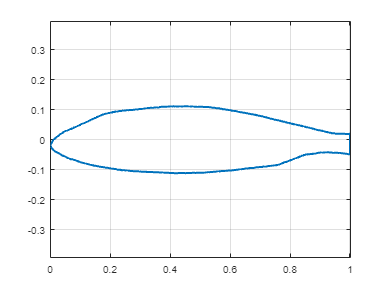

xs = [boundaries_body{1}(:,1) boundaries_body{2}(:,1) boundaries_body{3}(:,1) boundaries_body{4}(:,1) boundaries_body{5}(:,1)];
ys = [boundaries_body{1}(:,2) boundaries_body{2}(:,2) boundaries_body{3}(:,2) boundaries_body{4}(:,2) boundaries_body{5}(:,2)];
average_body = [mean(xs,2) mean(ys,2)];
average_body = align_symmetrically(average_body);

figure;
hold on
plot(average_body(:,1),average_body(:,2), 'LineWidth',2)
grid on
box on
axis equal
hold off

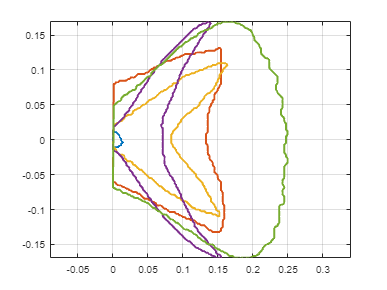

boundaries_tail = cell(length(masks),1);

figure;
hold on
for i=1:length(masks)
    fine_adjust = 0;
    XY = boundaries_norm{i};
    XY = XY(find(XY(:,1) >= 1),:);

    XY = arclength_resample(XY,512);

    XY = align_symmetrically(XY);

    boundaries_tail{i} = XY;

    plot(XY(:,1),XY(:,2), 'LineWidth',2)
end
grid on
box on
axis equal
hold off

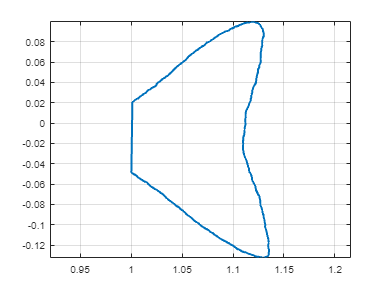

xs = [boundaries_tail{1}(:,1) boundaries_tail{2}(:,1) boundaries_tail{3}(:,1) boundaries_tail{4}(:,1) boundaries_tail{5}(:,1)];
ys = [boundaries_tail{1}(:,2) boundaries_tail{2}(:,2) boundaries_tail{3}(:,2) boundaries_tail{4}(:,2) boundaries_tail{5}(:,2)];
average_tail = [mean(xs,2) mean(ys,2)];
average_tail = align_symmetrically(average_tail);
average_tail(:,1) = average_tail(:,1)+1;
average_tail(:,2) = average_tail(:,2)-abs(average_tail(1,2)-average_body(256,2));

figure;
hold on
plot(average_tail(:,1),average_tail(:,2), 'LineWidth',2)
grid on
box on
axis equal
hold off

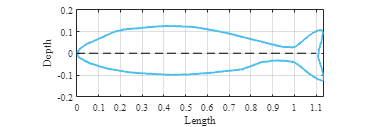

average_fish = [average_body(1:255,:); average_tail(1:end-1,:); average_body(258:end,:)];

average_fish = rotateBoundary(average_fish,-0.5,[0,0]);
average_fish = align_symmetrically(average_fish);

figure;
hold on
plot(average_fish(:,1),average_fish(:,2), 'LineWidth',2,'Color',[0.3010 0.7450 0.9330])

midline_x = 0:0.05:max(average_fish(:,1));
midline_y = zeros(length(midline_x),1);
plot(midline_x,midline_y,'black--')

grid on
box on
axis equal

ylim([-0.2 0.2])
xlim([0 max(average_fish(:,1))])
yticks(-0.2:0.1:0.2)
xticks(0:0.1:max(average_fish(:,1)))
fontsize(10,'points')
fontname("Times New Roman")
ylabel("Depth","Interpreter","tex")
xlabel('Length','interpreter','tex')
set(gca,'TickLabelInterpreter','tex')

x0=10;
y0=10;
w=15;
h=w*2*0.1641;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
hold off

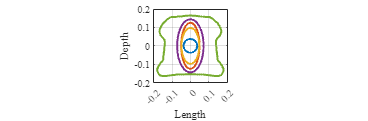

boundaries_cross = cell(length(masks),1);
N = 128;
figure;
hold on
for i=1:length(masks)-1
    a = (max(boundaries_body{i}(:,2))-min(boundaries_body{i}(:,2)))/2;

    XY = ellipse(a,a/2,N);

    if i == 1
        XY = ellipse(a,a,N);
    end
    
    if i == 2
        XY = ellipse(a,a/2.5,N);
    end

    boundaries_cross{i} = XY;

    plot(XY(:,1),XY(:,2), 'LineWidth',2)
end
im_front_boxfish = load_fish_image('fish-annotations\boxfish\ostraciiform-ostracion-cubicum-annotated-front.png');
boundary_front_boxfish = get_boundary(im_front_boxfish);
XY = align_symmetrically(boundary_front_boxfish);
XY(:,2) = -XY(:,2);
XY = [XY(413:end,:); XY(1:412,:)];
XYtop = XY(1:426,:);
XYtop = resampleNPoints(XYtop,64);
XYbottom = XY(427:end,:);
[~,idx] = unique(XYbottom,"rows");
XYbottom = XYbottom(sort(idx),:);
XYbottom = resampleNPoints(XYbottom,64);
XY = [XYtop; XYbottom(2:end,:)];
XY(end+1,:) = XY(1,:);
xmin = min(XY(:,1));
xmax = max(XY(:,1));
xrange = xmax-xmin;
XY(:,1) = XY(:,1)-xmin-xrange/2;
a = (max(boundaries_body{5}(:,2))-min(boundaries_body{5}(:,2)))/2;
scale = a/((max(boundary_front_boxfish(:,2))-min(boundary_front_boxfish(:,2)))/2);
XY = XY*scale;
boundaries_cross{5} = XY;
plot(XY(:,1),XY(:,2), 'LineWidth',2)
x0=10;
y0=10;
w=13;
h=w*2*0.1641;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
grid on
box on
axis equal
ylim([-0.2 0.2])
xlim([-0.2 0.2])
yticks(-0.2:0.1:0.2)
xticks(-0.2:0.1:0.2)
fontsize(10,'points')
fontname("Times New Roman")
ylabel("Depth","Interpreter","tex")
xlabel('Length','interpreter','tex')
set(gca,'TickLabelInterpreter','tex')
hold off

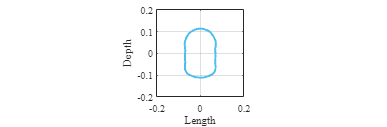

xs = [boundaries_cross{1}(:,1) boundaries_cross{2}(:,1) boundaries_cross{3}(:,1) boundaries_cross{4}(:,1) boundaries_cross{5}(:,1)];
ys = [boundaries_cross{1}(:,2) boundaries_cross{2}(:,2) boundaries_cross{3}(:,2) boundaries_cross{4}(:,2) boundaries_cross{5}(:,2)];
average_cross = [mean(xs,2) mean(ys,2)];

figure;
hold on
plot(average_cross(:,1),average_cross(:,2), 'LineWidth',2,'Color',[0.3010 0.7450 0.9330])
x0=10;
y0=10;
w=15;
h=w*2*0.1641;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
grid on
box on
axis equal
ylim([-0.2 0.2])
xlim([-0.2 0.2])
yticks(-0.2:0.1:0.2)
%xticks(-0.2:0.1:0.2)
fontsize(10,'points')
fontname("Times New Roman")
ylabel("Depth","Interpreter","tex")
xlabel('Length','interpreter','tex')
set(gca,'TickLabelInterpreter','tex')
hold off

%% ============================================================
% MORPHOLOGY EXTRACTION
%% ============================================================

species = { ...
    'eel',...
    'trout',...
    'mackerel',...
    'tuna',...
    'boxfish',...
    'average'};

bodySet = { ...
    boundaries_body{1},...
    boundaries_body{2},...
    boundaries_body{3},...
    boundaries_body{4},...
    boundaries_body{5},...
    average_body};

tailSet = { ...
    boundaries_tail{1},...
    boundaries_tail{2},...
    boundaries_tail{3},...
    boundaries_tail{4},...
    boundaries_tail{5},...
    average_tail};

crossSet = { ...
    boundaries_cross{1},...
    boundaries_cross{2},...
    boundaries_cross{3},...
    boundaries_cross{4},...
    boundaries_cross{5},...
    average_cross};

pedFiles = { ...
'fish-annotations\eel\anguilliform-anguilla-anguilla-annotated-peduncle.png',...
'fish-annotations\trout\subcarangiform-oncorhynchus-mykiss-annotated-peduncle.png',...
'fish-annotations\mackerel\carangiform-scomber-scombrus-annotated-peduncle.png',...
'fish-annotations\tuna\thunniform-thunnus-thynnus-annotated-peduncle.png',...
'fish-annotations\boxfish\ostraciiform-ostracion-cubicum-annotated-peduncle.png'};

morph = struct();

for i=1:length(bodySet)

    body = bodySet{i};
    tail = tailSet{i};
    cross = crossSet{i};

    %% --------------------------------------------------------
    % TOTAL LENGTH
    %% --------------------------------------------------------

    bodyLength = ...
        max(body(:,1));

    tailLength = ...
        max(tail(:,1));

    morph(i).TL = ...
        bodyLength + tailLength;

    if i == 6
        morph(i).TL = tailLength;
    end

    %% --------------------------------------------------------
    % BODY DEPTH PROFILE
    %% --------------------------------------------------------

    xq = linspace(0,1,300);

    idxSplit = round(size(body,1)/2);

    upper = body(1:idxSplit,:);
    lower = body(idxSplit+1:end,:);

    upper = sortrows(upper,1);
    lower = sortrows(lower,1);

    [xu,iu] = unique(upper(:,1));
    [xl,il] = unique(lower(:,1));

    yu = interp1( ...
        xu,...
        upper(iu,2),...
        xq,...
        'linear',...
        'extrap');

    yl = interp1( ...
        xl,...
        lower(il,2),...
        xq,...
        'linear',...
        'extrap');

    h = abs(yu-yl);

    morph(i).bodyProfile = h;

    [bodyDepth,idxMax] = max(h);

    morph(i).bodyDepth = ...
        bodyDepth;

    morph(i).bodyDepthPos = ...
        xq(idxMax);

    morph(i).fineness = ...
        1/bodyDepth;

    %% --------------------------------------------------------
    % PEDUNCLE
    %% --------------------------------------------------------

    if i < 6 && i > 1

        imPed = load_fish_image( ...
            pedFiles{i});

        scaleFactor = ...
            SL_min/SLs(i);

        imPed = imresize( ...
            imPed,...
            scaleFactor,...
            'nearest');

        pedLength = ...
            size(imPed,2) ...
            /SL_min;

        pedDepth = inf;

        for k=1:size(imPed,2)

            temp = ...
                find(~imPed(:,k));

            if ~isempty(temp)

                pedDepth = ...
                    min( ...
                    pedDepth,...
                    length(temp));

            end

        end

        pedDepth = ...
            pedDepth/SL_min;

        morph(i).pedLength = ...
            pedLength;

        morph(i).pedDepth = ...
            pedDepth;

        morph(i).pedSlenderness = ...
            pedDepth/bodyDepth;

    else

        pedMask = ...
            xq >= 0.75 & ...
            xq <= 1.00;

        pedDepth = ...
            min(h(pedMask));

        pedX = ...
            xq(pedMask);

        rearH = ...
            h(pedMask);

        threshold = ...
            pedDepth + ...
            0.15*(bodyDepth-pedDepth);

        idxStart = ...
            find( ...
            rearH<=threshold,...
            1,...
            'first');

        morph(i).pedLength = ...
            1-pedX(idxStart);

        morph(i).pedDepth = ...
            pedDepth;

        morph(i).pedSlenderness = ...
            pedDepth/bodyDepth;

    end

    %% --------------------------------------------------------
    % CAUDAL
    %% --------------------------------------------------------

    tailPts = ...
        unique( ...
        tail,...
        'rows',...
        'stable');

    tailPoly = polyshape( ...
        tailPts(:,1),...
        tailPts(:,2),...
        'Simplify',...
        true);

    caudalSpan = ...
        max(tail(:,2)) ...
        - min(tail(:,2));

    caudalArea = ...
        area(tailPoly);

    caudalLength = ...
        max(tail(:,1)) ...
        - min(tail(:,1));

    morph(i).caudalSpan = ...
        caudalSpan;

    morph(i).caudalArea = ...
        caudalArea;

    morph(i).caudalLength = ...
        caudalLength;

    morph(i).aspectRatio = ...
        caudalSpan^2 ...
        /caudalArea;

    morph(i).meanChord = ...
        caudalArea ...
        /caudalSpan;

    %% --------------------------------------------------------
    % BODY WIDTH
    %% --------------------------------------------------------

    morph(i).bodyWidth = ...
        max(cross(:,1)) ...
        - min(cross(:,1));

    %% --------------------------------------------------------
    % FRONTAL AREA
    %% --------------------------------------------------------

    crossPts = unique( ...
        cross,...
        'rows',...
        'stable');

    crossPoly = polyshape( ...
        crossPts(:,1),...
        crossPts(:,2),...
        'Simplify',...
        true);

    morph(i).frontalArea = ...
        area(crossPoly);

    %% --------------------------------------------------------
    % BODY AREA
    %% --------------------------------------------------------

    bodyPts = unique( ...
        body,...
        'rows',...
        'stable');

    bodyPoly = polyshape( ...
        bodyPts(:,1),...
        bodyPts(:,2),...
        'Simplify',...
        true);

    morph(i).bodyArea = ...
        area(bodyPoly);

end


%% ============================================================
% OUTPUT TABLE
%% ============================================================

Species = string(species)';

TL = [morph.TL]';

BodyDepth = [morph.bodyDepth]';
BodyDepthPos = [morph.bodyDepthPos]';
Fineness = [morph.fineness]';

PedLength = [morph.pedLength]';
PedDepth = [morph.pedDepth]';
PedSlenderness = [morph.pedSlenderness]';

FrontalArea = [morph.frontalArea]';

CaudalSpan = [morph.caudalSpan]';
CaudalLength = [morph.caudalLength]';
CaudalArea = [morph.caudalArea]';
AspectRatio = [morph.aspectRatio]';
MeanChord = [morph.meanChord]';

BodyWidth = [morph.bodyWidth]';
BodyArea = [morph.bodyArea]';

MorphTable = table( ...
Species,TL,...
BodyDepth,BodyDepthPos,Fineness,...
PedLength,PedDepth,PedSlenderness,...
FrontalArea,...
CaudalSpan,CaudalLength,CaudalArea,...
AspectRatio,MeanChord,...
BodyWidth,BodyArea);

disp(MorphTable)

     Species        TL      BodyDepth    BodyDepthPos    Fineness    PedLength    PedDepth    PedSlenderness    FrontalArea    CaudalSpan    CaudalLength    CaudalArea    AspectRatio    MeanChord    BodyWidth    BodyArea
    __________    ______    _________    ____________    ________    _________    ________    ______________    ___________    __________    ____________    __________    ___________    _________    _________    ________

    "eel"    

function im = load_fish_image(path)
    im = imread(path);
    im = rgb2gray(im);
    im = imbinarize(im);
end

function XY = ellipse(a,b,N)
    t = linspace(0,2*pi,N);
    x = b*cos(t);
    y = a*sin(t);
    XY = [x',y'];
end

function XY = resampleNPoints(xy,N)
    s = [0; cumsum(hypot(diff(xy(:,1)), diff(xy(:,2))))];
    s = s./s(end);
    t = linspace(0,1,N+1)'; t(end) = []; % N points, closed separately if needed
    x = interp1(s, xy(:,1), t, 'linear');
    y = interp1(s, xy(:,2), t, 'linear');
    %x(end+1) = x(1); y(end+1) = y(1);
    XY = [x,y];
end

function R = rotateBoundary(P, angleDeg, center)
%ROTATEBOUNDARY Rotate a set of 2-D boundary points by angleDeg (degrees).
%   P         : Nx2 array of [x y] points
%   angleDeg  : rotation angle in degrees (CCW, standard Cartesian coords)
%   center    : 1x2 [cx cy] rotation center (optional).
%               If omitted or empty, uses centroid mean(P,1).
%
%   R         : Nx2 array of rotated points

    arguments
        P (:,2) double
        angleDeg (1,1) double
        center (1,2) double = []
    end

    if isempty(center)
        center = mean(P, 1);  % centroid
    end

    theta = deg2rad(angleDeg);
    Rmat  = [cos(theta) -sin(theta); 
             sin(theta)  cos(theta)];

    R = (P - center) * Rmat.' + center; % rotate about 'center'
end

function xy = align_symmetrically(xy)
    x = xy(:,1);
    y = xy(:,2);
    
    x_min = min(x);
    y_min = min(y);
    y_max = max(y);
    y_range = y_max-y_min;

    xy = [x-x_min, y-y_min-y_range/2];
end

function xy = get_boundary(bw)
    B = bwboundaries(~bw); [~,iMax] = max(cellfun(@(b) size(b,1), B)); xy = B{iMax};
    xy = fliplr(xy); % bwboundaries returns [row,col]; swap to [x,y]
    xy = flipud(xy); % bwboundaries returns [row,col]; swap to [x,y]
    xy = unique(xy,'rows','stable'); % avoid duplicates
    if ~isequal(xy(1,:), xy(end,:)), xy(end+1,:) = xy(1,:); end
end

function XY = arclength_resample(xy, N)
    s = [0; cumsum(hypot(diff(xy(:,1)), diff(xy(:,2))))];
    s = s./s(end);
    t = linspace(0,1,N+1)'; t(end) = [];
    xu = interp1(s, xy(:,1), t, 'linear');
    yu = interp1(s, xy(:,2), t, 'linear');
    xu(end+1) = xu(1); yu(end+1) = yu(1);
    XY = [xu,yu];
end